# Bandpass Filtering Script (Gaussian Filter)

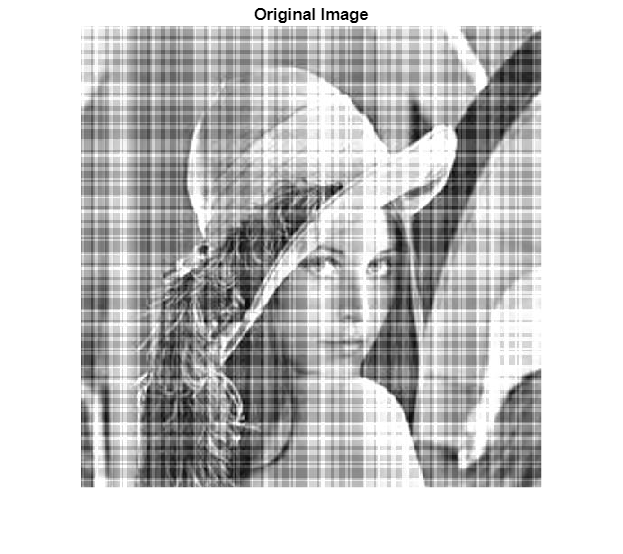

% This script implements a Gaussian Bandpass filter in the frequency domain
% and applies it to an input grayscale image.
%
% Before running, ensure you have a grayscale image loaded in your workspace,
% for example, by using:
%
   inputImage = imread('image.png'); % Replace 'your_image.jpg' with your image file
   if size(inputImage, 3) == 3
       inputImage = rgb2gray(inputImage);
   end
%
% You can adjust the filter parameters D0, W below.

% --- Parameters (Adjust these values as needed) ---
D0 = 50;      % Center frequency of the bandpass filter
W = 30;       % Bandwidth of the bandpass filter

% --- Input Image (Assuming 'inputImage' is already in your workspace) ---
if ~exist('inputImage', 'var')
    error('Error: Input image ''inputImage'' not found in workspace. Please load a grayscale image into ''inputImage'' first.');
end

% Convert input image to double if it's uint8 for calculations
if isa(inputImage, 'uint8')
    img_double = im2double(inputImage);
else
    img_double = inputImage;
end

% 1. Fourier Transform of the image
FT_img = fft2(img_double);
FT_img_shifted = fftshift(FT_img); % Shift zero frequency to the center

% 2. Design a Gaussian Bandpass Filter in the frequency domain
[M, N] = size(img_double);
[X, Y] = meshgrid(1:N, 1:M);
centerX = ceil(N/2); centerY = ceil(M/2);
D = sqrt((X - centerX - 1).^2 + (Y - centerY - 1).^2); % Distance from center

% Gaussian Bandpass Filter Transfer Function
H_bandpass = exp(-(D.^2)./(2*(W/2).^2)) .* (1 - exp(-(D.^2)./(2*D0.^2)));

% 3. Apply the Bandpass Filter in the frequency domain
filtered_FT_shifted = H_bandpass .* FT_img_shifted;
filtered_FT = ifftshift(filtered_FT_shifted); % Shift zero frequency back to corner

% 4. Inverse Fourier Transform to get the filtered image in spatial domain
filtered_img_double = ifft2(filtered_FT);

% 5. Convert back to uint8 for display purposes if original image was uint8
if isa(inputImage, 'uint8')
    filtered_image = im2uint8(real(filtered_img_double)); % Take real part and convert to uint8
else
    filtered_image = real(filtered_img_double); % Take real part
end

% --- Display Results ---
figure; imshow(inputImage); title('Original Image');

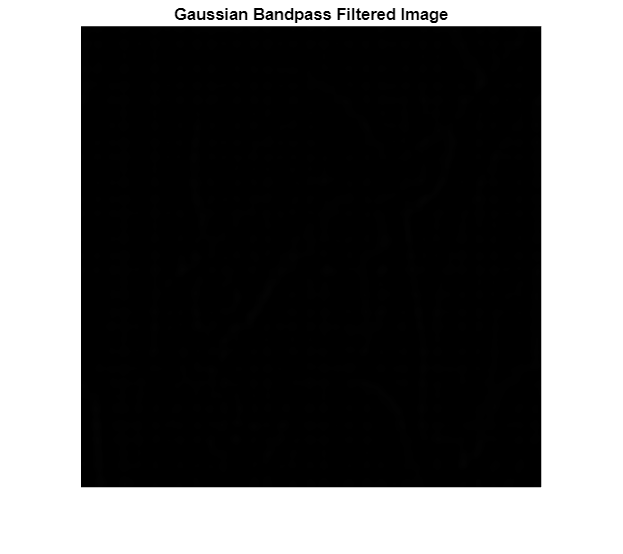

figure; imshow(filtered_image); title('Gaussian Bandpass Filtered Image');

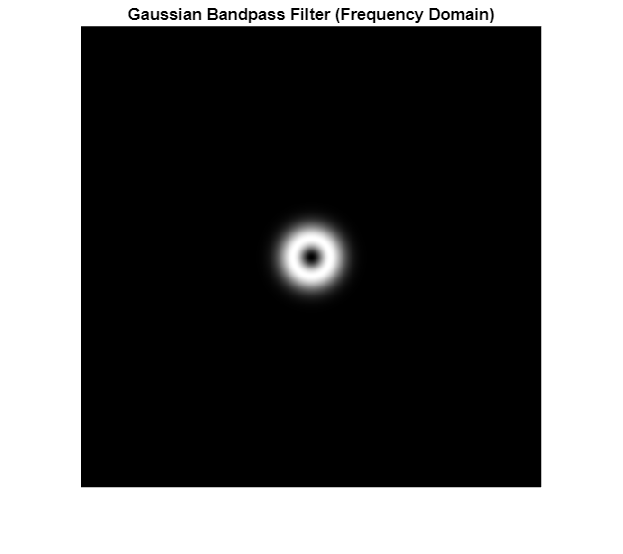

% Display the filter in frequency domain
figure; imshow(H_bandpass, []); title('Gaussian Bandpass Filter (Frequency Domain)');

## Bandreject (Bandstop) Filtering Script (Gaussian Filter)

% This script implements a Gaussian Bandreject (Bandstop) filter in the frequency domain
% and applies it to an input grayscale image.
%
% Before running, ensure you have a grayscale image loaded in your workspace,
% for example, by using:
%
   inputImage = imread('image.png'); % Replace 'your_image.jpg' with your image file
   if size(inputImage, 3) == 3
       inputImage = rgb2gray(inputImage);
   end
%
% You can adjust the filter parameters D0, W below.

% --- Parameters (Adjust these values as needed) ---
D0_reject = 50;    % Center frequency of the bandreject filter
W_reject = 30;     % Bandwidth of the bandreject filter

% --- Input Image (Assuming 'inputImage' is already in your workspace) ---
if ~exist('inputImage', 'var')
    error('Error: Input image ''inputImage'' not found in workspace. Please load a grayscale image into ''inputImage'' first.');
end

% Convert input image to double if it's uint8 for calculations
if isa(inputImage, 'uint8')
    img_double_reject = im2double(inputImage);
else
    img_double_reject = inputImage;
end

% 1. Fourier Transform of the image
FT_img_reject = fft2(img_double_reject);
FT_img_shifted_reject = fftshift(FT_img_reject); % Shift zero frequency to the center

% 2. Design a Gaussian Bandreject Filter in the frequency domain
[M_reject, N_reject] = size(img_double_reject);
[X_reject, Y_reject] = meshgrid(1:N_reject, 1:M_reject);
centerX_reject = ceil(N_reject/2); centerY_reject = ceil(M_reject/2);
D_reject = sqrt((X_reject - centerX_reject - 1).^2 + (Y_reject - centerY_reject - 1).^2); % Distance from center

% Gaussian Bandreject Filter Transfer Function
H_bandreject = 1 - exp(-(D_reject.^2)./(2*((W_reject/2)).^2)) .* (exp(-(D_reject.^2)./(2*D0_reject.^2)));


% 3. Apply the Bandreject Filter in the frequency domain
filtered_FT_shifted_reject = H_bandreject .* FT_img_shifted_reject;
filtered_FT_reject = ifftshift(filtered_FT_shifted_reject); % Shift zero frequency back to corner

% 4. Inverse Fourier Transform to get the filtered image in spatial domain
filtered_img_double_reject = ifft2(filtered_FT_reject);

% 5. Convert back to uint8 for display purposes if original image was uint8
if isa(inputImage, 'uint8')
    filtered_image_reject = im2uint8(real(filtered_img_double_reject)); % Take real part and convert to uint8
else
    filtered_image_reject = real(filtered_img_double_reject); % Take real part
end

% --- Display Results ---
figure; imshow(inputImage); title('Original Image');

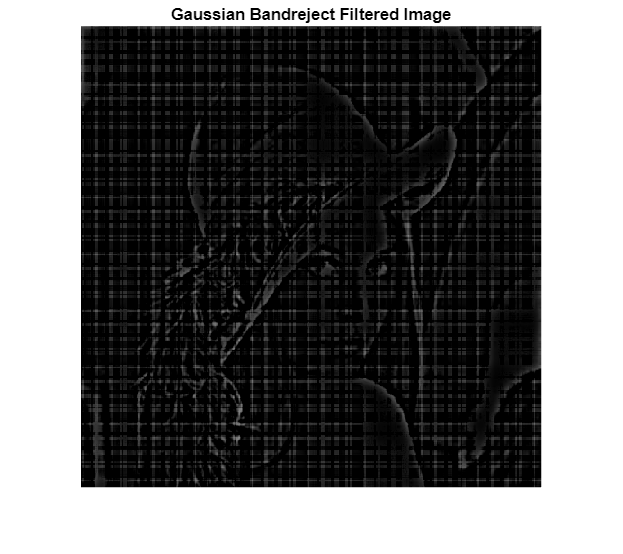

figure; imshow(filtered_image_reject); title('Gaussian Bandreject Filtered Image');

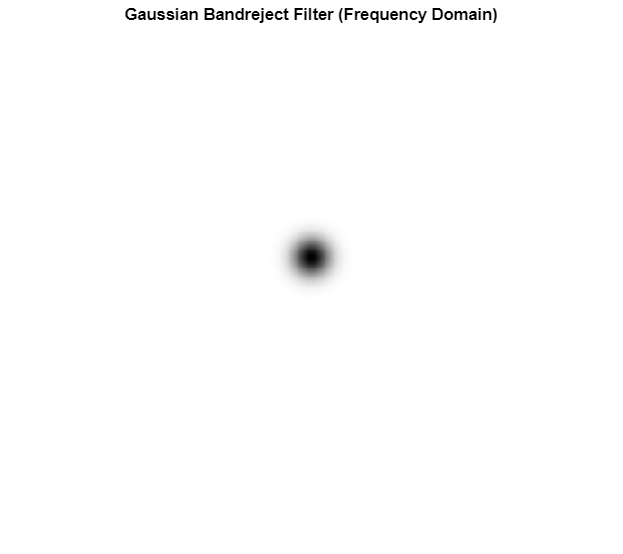

% Display the filter in frequency domain
figure; imshow(H_bandreject, []); title('Gaussian Bandreject Filter (Frequency Domain)')%% Bandpass Filtering Script (Gaussian Filter)


% This script implements a Gaussian Bandpass filter in the frequency domain
% and applies it to an input grayscale image.
%
% Before running, ensure you have a grayscale image loaded in your workspace,
% for example, by using:
%
%   inputImage = imread('your_image.jpg'); % Replace 'your_image.jpg' with your image file
%   if size(inputImage, 3) == 3
%       inputImage = rgb2gray(inputImage);
%   end
%
% You can adjust the filter parameters D0, W below.

% --- Parameters (Adjust these values as needed) ---
D0 = 50;      % Center frequency of the bandpass filter
W = 30;       % Bandwidth of the bandpass filter

% --- Input Image (Assuming 'inputImage' is already in your workspace) ---
if ~exist('inputImage', 'var')
    error('Error: Input image ''inputImage'' not found in workspace. Please load a grayscale image into ''inputImage'' first.');
end

% Convert input image to double if it's uint8 for calculations
if isa(inputImage, 'uint8')
    img_double = im2double(inputImage);
else
    img_double = inputImage;
end

% 1. Fourier Transform of the image
FT_img = fft2(img_double);
FT_img_shifted = fftshift(FT_img); % Shift zero frequency to the center

% 2. Design a Gaussian Bandpass Filter in the frequency domain
[M, N] = size(img_double);
[X, Y] = meshgrid(1:N, 1:M);
centerX = ceil(N/2); centerY = ceil(M/2);
D = sqrt((X - centerX - 1).^2 + (Y - centerY - 1).^2); % Distance from center

% Gaussian Bandpass Filter Transfer Function
H_bandpass = exp(-(D.^2)./(2*(W/2).^2)) .* (1 - exp(-(D.^2)./(2*D0.^2)));

% 3. Apply the Bandpass Filter in the frequency domain
filtered_FT_shifted = H_bandpass .* FT_img_shifted;
filtered_FT = ifftshift(filtered_FT_shifted); % Shift zero frequency back to corner

% 4. Inverse Fourier Transform to get the filtered image in spatial domain
filtered_img_double = ifft2(filtered_FT);

% 5. Convert back to uint8 for display purposes if original image was uint8
if isa(inputImage, 'uint8')
    filtered_image = im2uint8(real(filtered_img_double)); % Take real part and convert to uint8
else
    filtered_image = real(filtered_img_double); % Take real part
end

% --- Display Results ---
figure; imshow(inputImage); title('Original Image');

figure; imshow(filtered_image); title('Gaussian Bandpass Filtered Image');

% Display the filter in frequency domain
figure; imshow(H_bandpass, []); title('Gaussian Bandpass Filter (Frequency Domain)');

## Bandreject (Bandstop) Filtering Script (Gaussian Filter)

% This script implements a Gaussian Bandreject (Bandstop) filter in the frequency domain
% and applies it to an input grayscale image.
%
% Before running, ensure you have a grayscale image loaded in your workspace,
% for example, by using:
%
%   inputImage = imread('your_image.jpg'); % Replace 'your_image.jpg' with your image file
%   if size(inputImage, 3) == 3
%       inputImage = rgb2gray(inputImage);
%   end
%
% You can adjust the filter parameters D0, W below.

% --- Parameters (Adjust these values as needed) ---
D0_reject = 50;    % Center frequency of the bandreject filter
W_reject = 30;     % Bandwidth of the bandreject filter

% --- Input Image (Assuming 'inputImage' is already in your workspace) ---
if ~exist('inputImage', 'var')
    error('Error: Input image ''inputImage'' not found in workspace. Please load a grayscale image into ''inputImage'' first.');
end

% Convert input image to double if it's uint8 for calculations
if isa(inputImage, 'uint8')
    img_double_reject = im2double(inputImage);
else
    img_double_reject = inputImage;
end

% 1. Fourier Transform of the image
FT_img_reject = fft2(img_double_reject);
FT_img_shifted_reject = fftshift(FT_img_reject); % Shift zero frequency to the center

% 2. Design a Gaussian Bandreject Filter in the frequency domain
[M_reject, N_reject] = size(img_double_reject);
[X_reject, Y_reject] = meshgrid(1:N_reject, 1:M_reject);
centerX_reject = ceil(N_reject/2); centerY_reject = ceil(M_reject/2);
D_reject = sqrt((X_reject - centerX_reject - 1).^2 + (Y_reject - centerY_reject - 1).^2); % Distance from center

% Gaussian Bandreject Filter Transfer Function
H_bandreject = 1 - exp(-(D_reject.^2)./(2*((W_reject/2)).^2)) .* (exp(-(D_reject.^2)./(2*D0_reject.^2)));


% 3. Apply the Bandreject Filter in the frequency domain
filtered_FT_shifted_reject = H_bandreject .* FT_img_shifted_reject;
filtered_FT_reject = ifftshift(filtered_FT_shifted_reject); % Shift zero frequency back to corner

% 4. Inverse Fourier Transform to get the filtered image in spatial domain
filtered_img_double_reject = ifft2(filtered_FT_reject);

% 5. Convert back to uint8 for display purposes if original image was uint8
if isa(inputImage, 'uint8')
    filtered_image_reject = im2uint8(real(filtered_img_double_reject)); % Take real part and convert to uint8
else
    filtered_image_reject = real(filtered_img_double_reject); % Take real part
end

% --- Display Results ---
figure; imshow(inputImage); title('Original Image');

figure; imshow(filtered_image_reject); title('Gaussian Bandreject Filtered Image');

% Display the filter in frequency domain
figure; imshow(H_bandreject, []); title('Gaussian Bandreject Filter (Frequency Domain)');;